### **Bildvergleich** (Lea, Clara)

Für den Bildvergleich betrachten wir nur die Helligkeitsverteilung von Bildern. Diese liegen zwischen Schwarz und Weiß und nehmen daher Werte zwischen 0 und 1 an. Bei der Umsetzung als Programm sind die Helligkeitswerte Integer und reichen zbsp. von 0 bis 255. (= digital quantisiertes Bild).

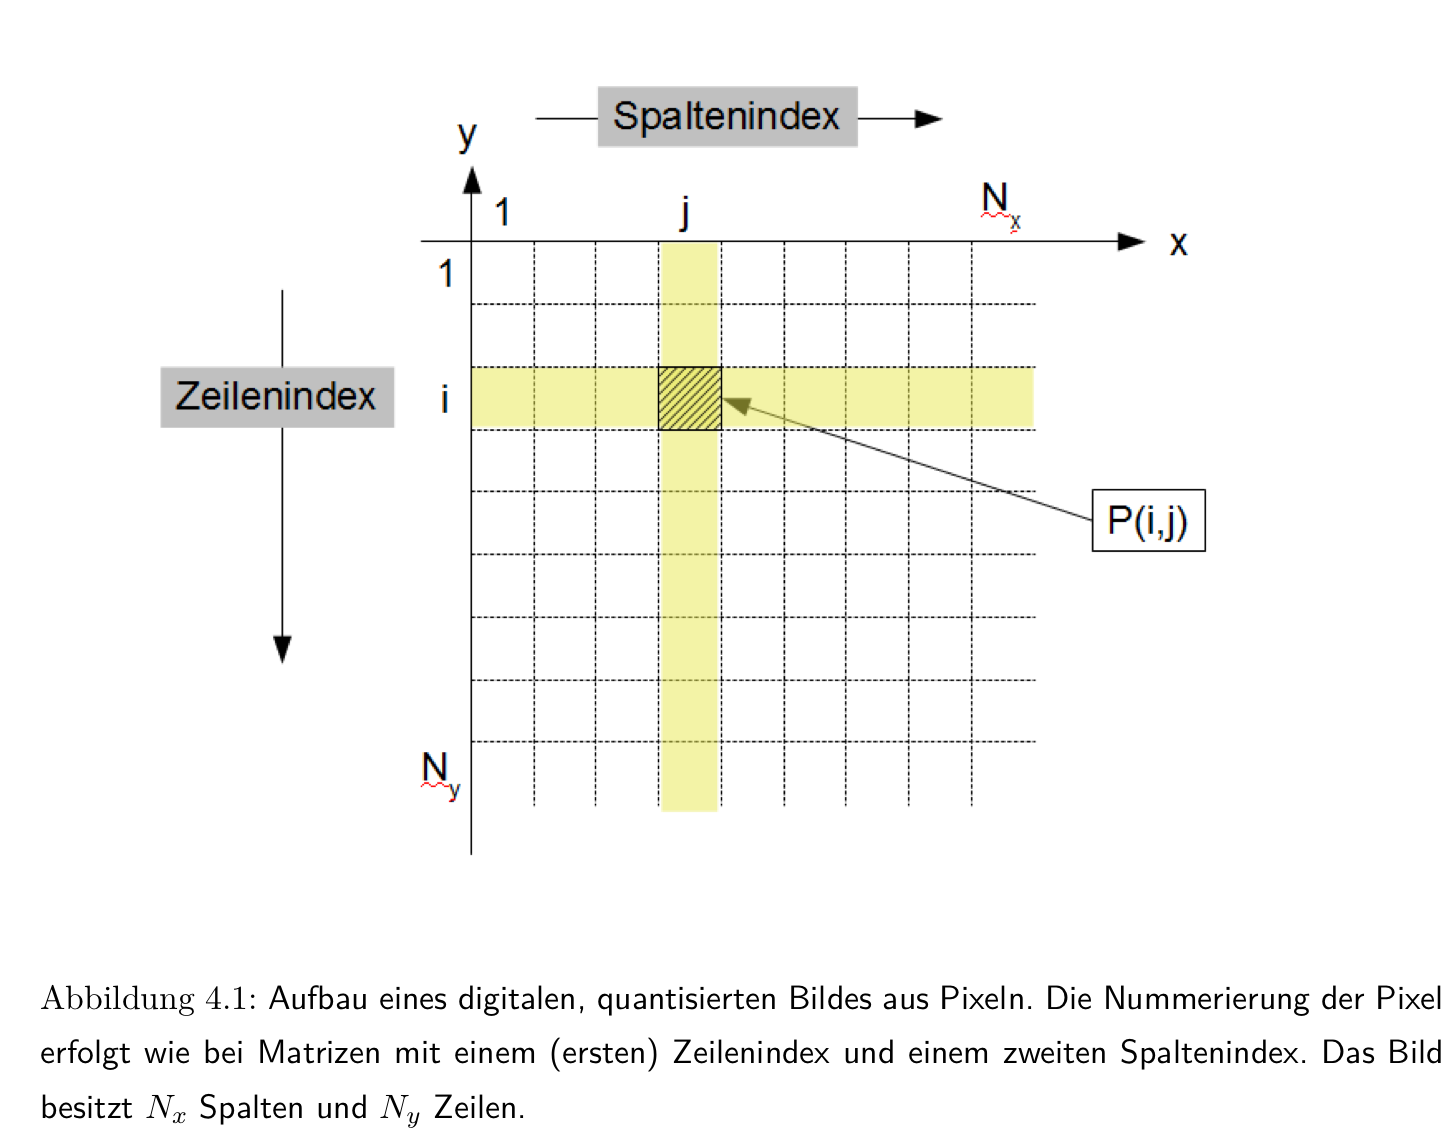 

(Quelle: Fuchs, C.: Computer Tomopgrafie Skript. 2022)

Für die Simulation eines tomografischen Verfahrens soll betrachtet werden, wie gut das Ergebnisbild R das ursprüngliche Bild A reproduziert. Dafür haben wir 5 Kennzahlen betrachtet.

% Einfaches Beispiel eines Augangsbild A und Ereignisbildes R
R = [[1,2,3];[1,2,3]];
A = [[1,2,3];[1,2,4]];

% Beispiel eines Augangsbild A und Ereignisbildes R, die komplett gleich
% sind
R_gleich = [[1,1,1];[1,1,1]];
A_gleich = [[1,1,1];[1,1,1]];

% Beispiel eines Augangsbild A und Ereignisbildes R, die maximal
% verschieden sind
R_verschieden = [[10,0,10];[0,10,0]];
A_verschieden = [[0,10,0];[10,0,10]];

**Kennzahl 1**

$\Delta_1$ hat den Wertebereich von 0 bis M, wobei M der größte Werte ist, den einer der Pixel annimmt. $\Delta_1$ wird 0, wenn die Bilder A und R gleich sind und M, wenn sie maximal verschieden sind.


$$\Delta_1 \left(R,A\right)=\frac{1}{N_{x\;} N_y }\;\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|r_{\textrm{ij}} -a_{\textrm{ij}} \right|$$


del1 = (1/ (size(A,1)*size(A,2))) * sum(sum(abs(R-A)));
disp(del1)

    0.1667



del1 = (1/ (size(A_gleich,1)*size(A_gleich,2))) * sum(sum(abs(R_gleich-A_gleich)));
disp(del1)

     0



del1 = (1/ (size(A_verschieden,1)*size(A_verschieden,2))) * sum(sum(abs(R_verschieden-A_verschieden)));
disp(del1)

    10



**Kennzahl 2**

$\Delta_2$ hat den Wertebereich von 0 bis M, wobei M der größte Werte ist, den einer der Pixel annimmt. $\Delta_2$ wird 0, wenn die Bilder A und R gleich sind und M, wenn sie maximal verschieden sind.


$$\Delta_2 \left(R,A\right)=\sqrt{\frac{1}{N_{x\;} N_y }\;\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left|r_{\textrm{ij}} -a_{\textrm{ij}} \right|}^2 }$$


del2 = sqrt((1/ (size(A,1)*size(A,2))) * sum(sum((R-A).^2)));
disp(del2)

    0.4082



del2 = sqrt((1/ (size(A_gleich,1)*size(A_gleich,2))) * sum(sum((R_gleich-A_gleich).^2)));
disp(del2)

     0



del2 = sqrt((1/ (size(A_verschieden,1)*size(A_verschieden,2))) * sum(sum((R_verschieden-A_verschieden).^2)));
disp(del2)

    10



Da M normalerweise unbekannt ist, ist es schwer ist mit den Kennzahlen 1 und 2 Rückschlüsse auf die Güte der Bildrekonstruktion zu ziehen. Deshalb werden weitere Kennzahlen benutzt.

**Kennzahl 3**


$$\Delta_3 \left(R,A\right)=\frac{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left(a_{\textrm{ij}} -r_{\textrm{ij}} \right)}^2 }{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left(a_{\textrm{ij}} +r_{\textrm{ij}} \right)}^2 }$$


Da $a_{\textrm{ij}}$ und $r_{\textrm{ij}}$ positiv sind, gilt: $0\le \Delta_3 \left(R,A\right)\le 1$

Wenn $\Delta_3$ = 0 ist, sind die Bilder wieder gleich. Bei $\Delta_3 \left(R,A\right)$ = 1 gilt die Bedingung: 

$\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } a_{\textrm{ij}} r_{\textrm{ij}} =0$, $\forall i\;\epsilon \;\left\lbrace 1,\ldotp \ldotp \ldotp ,N_x \right\rbrace ,j\;\epsilon \;\left\lbrace 1,\ldotp \ldotp \ldotp ,N_y \right\rbrace \;a_{\textrm{ij}} r_{\textrm{ij}} =0$

Das heißt Pixelwerte am gleichen Pixel können nicht von 0 verschieden sein. Wichtig ist außerdem, dass der Wertebereich von $\Delta_3$ nach oben beschränkt ist (wegen der Quantisierung der Pixelwerte). $\Delta_3$ wird daher 1, wenn die Bilder maximal verschieden sind.

del3 = sum(sum((A-R).^2)) / sum(sum((A+R).^2));
disp(del3)

    0.0080



del3 = sum(sum((A_gleich-R_gleich).^2)) / sum(sum((A_gleich+R_gleich).^2));
disp(del3)

     0



del3 = sum(sum((A_verschieden-R_verschieden).^2)) / sum(sum((A_verschieden+R_verschieden).^2));
disp(del3)

     1



Zwei weitere Kennzahlen aus der Literatur wurden umgesetzt:

**Kennzahl 4**

$\Delta_4$ ist Null, wenn beide Bilder identisch sind. $\Delta_4$ wird groß, wenn viele kleine Unterschiede auftreten. Außerdem gilt:


$$\Delta_4 \left(R,A\right)=1\leftrightarrow r_{\textrm{ij}} =\bar{a} \;\forall i\;$$

$$\epsilon \;\left\lbrace 1,\ldotp \ldotp \ldotp ,N_x \right\rbrace ,j\;\epsilon \;\left\lbrace 1,\ldotp \ldotp \ldotp ,N_y \right\rbrace$$


Es wird ein homogenes Bild berechnet, dessen Mittelwert dem Mittelwert des ursprünglichen Bildes A entspricht. Schon kleine Bildunterschiede zwischen A und R sind bereits wesentlich, wenn sich A nur gering von einem konstanten Bild mit gleichem Mittelwert unterscheidet. 


$$\Delta_4 \left(R,A\right)=\frac{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left(a_{\textrm{ij}} -r_{\textrm{ij}} \right)}^2 }{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left(a_{\textrm{ij}} -\bar{a} \right)}^2 }$$


del4 = sum(sum((A-R).^2)) / sum(sum((A-(mean(A,"all"))).^2));
disp(del4)

    0.1463



del4 = sum(sum((A_gleich-R_gleich).^2)) / sum(sum((A_gleich-(mean(A_gleich,"all"))).^2));
disp(del4)

   NaN



Bei zwei gleichen Bildern, wird auch der Term im Nenner 0, was zu einer fehlerhaften Rechenausgabe führt (es darf nicht durch 0 geteilt werden). Es kann aber 0 als Ergebnis angenommen werden.

del4 = sum(sum((A_verschieden-R_verschieden).^2)) / sum(sum((A_verschieden-(mean(A_verschieden,"all"))).^2));
disp(del4)

     4



**Kennzahl 5**

$\Delta_5$ ist Null, wenn beide Bilder identisch sind.


$$\Delta_5 \left(R,A\right)=\frac{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|a_{\textrm{ij}} -r_{\textrm{ij}} \right|}{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|a_{\textrm{ij}} \right|}$$


del5 = sum(sum(abs(A-R))) / sum(sum(abs(A)));
disp(del5)

    0.0769



del5 = sum(sum(abs(A_gleich-R_gleich))) / sum(sum(abs(A_gleich)));
disp(del5)

     0



del5 = sum(sum(abs(A_verschieden-R_verschieden))) / sum(sum(abs(A_verschieden)));
disp(del5)

     2



**Uniformity Index (Gleichheitsindex)**

Zur Bewertung der Homogenität eines Bildes, kann man $\rho_{\textrm{UI}} \left(A\right)$ berechnen. Das Bild A wird dabei mit einem homogenen Bild B verglichen, dessen Pixelwerte dem Mittelwer von A entsprechen.

Der Gleicheitsindex nimmt den Wert 1 an, wenn das Bild A homogen ist.


$$\rho_{\textrm{UI}} \left(A\right)=1-\frac{1}{2}\;\frac{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|a_{\textrm{ij}} -\bar{a} \right|}{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|a_{\textrm{ij}} \right|}$$


uniformity = 1 - 1/2 *(sum(sum(abs(A-mean(A,'all'))))/sum(sum(abs(A))));
disp(uniformity)

    0.7949



Insgesamt geben die Kennzahlen in der Praxis Werte zur Orientierung an. Besonders beim Betrachten vieler Beispiele, können Kennzahlen schnell eine Einschätzung geben.

### **Parallelstrahltomographie**

Parallelstrahlen werden durch das Objekt auf einen Zeilendetektor geworfen. Bei diesen Strahlen ist ein Winkelbereich von 180° für die Rekonstruktion ausreichend (im Gegensatz zu einer Kegelstrahlprojektion zum Beispiel, die 360° benötigt).

### **Fächerstrahltomographie**

Die Strahlenquelle wirft ihre Strahlen fächerförmig durch das Objekt auf einen Zeilendetektor.

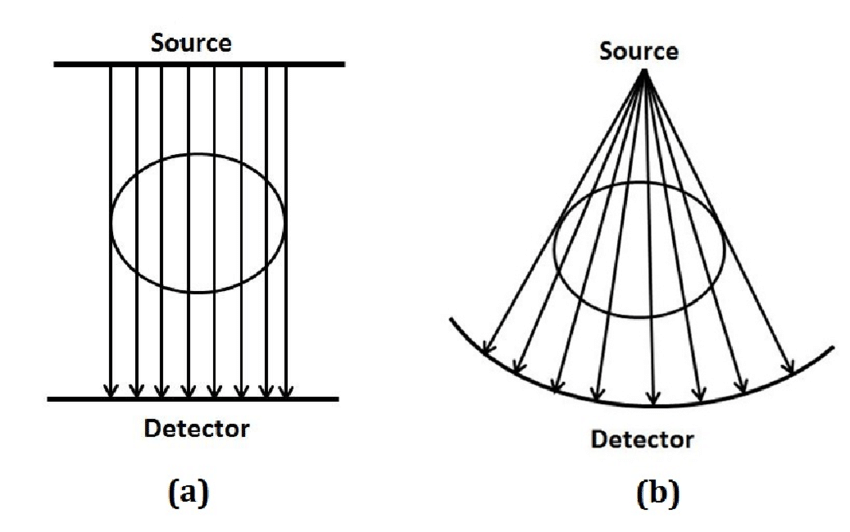([Quelle](https://www.researchgate.net/figure/Data-acquisition-in-a-Parallel-Beam-and-b-Fan-Beam-geometries_fig1_320527885))

Die Abbildung zeigt die Funktionsweise der Parallelstrahltomographie (a) und der Fächerstrahltomographie (b). Die Vorteile dieser Projektion sind unter anderem eine hohe Detailauflösung und eine schnelle Erzeugung eines Schnittbildes. Ein Nachteil sind jedoch die langen Messzeiten bei Volumenmessungen.

### **Kaczmarz Algorithmus**

Dient der interativen Lösung linearer Gleichungssysteme in der Form . Wobei *A* eine nichtsinguläre, also eine inversierbare, und unter Umständen überdefininiert Matrix ist. Das Ergebnis *b* stellt die gegebene Lösung, die anhand der gemessenen Daten vorliegen, dar. Der Lösungsvektor *x* wird mit dem Algorthmus iterativ bestimmt.

Die folgenden Formel beschreibt den Algrithmus, für die Bestimmung der Lösung *x*

 , mit ,

  als transponierte *i*-te Zeile der Matrix A, die quadriterte euklidische Norm und das Skalarprodukt von   und  .

Exemplarisch kann der Algorithmus zwei dimensional und überbestimmt mit der folgenden Grafik erklärt werden.

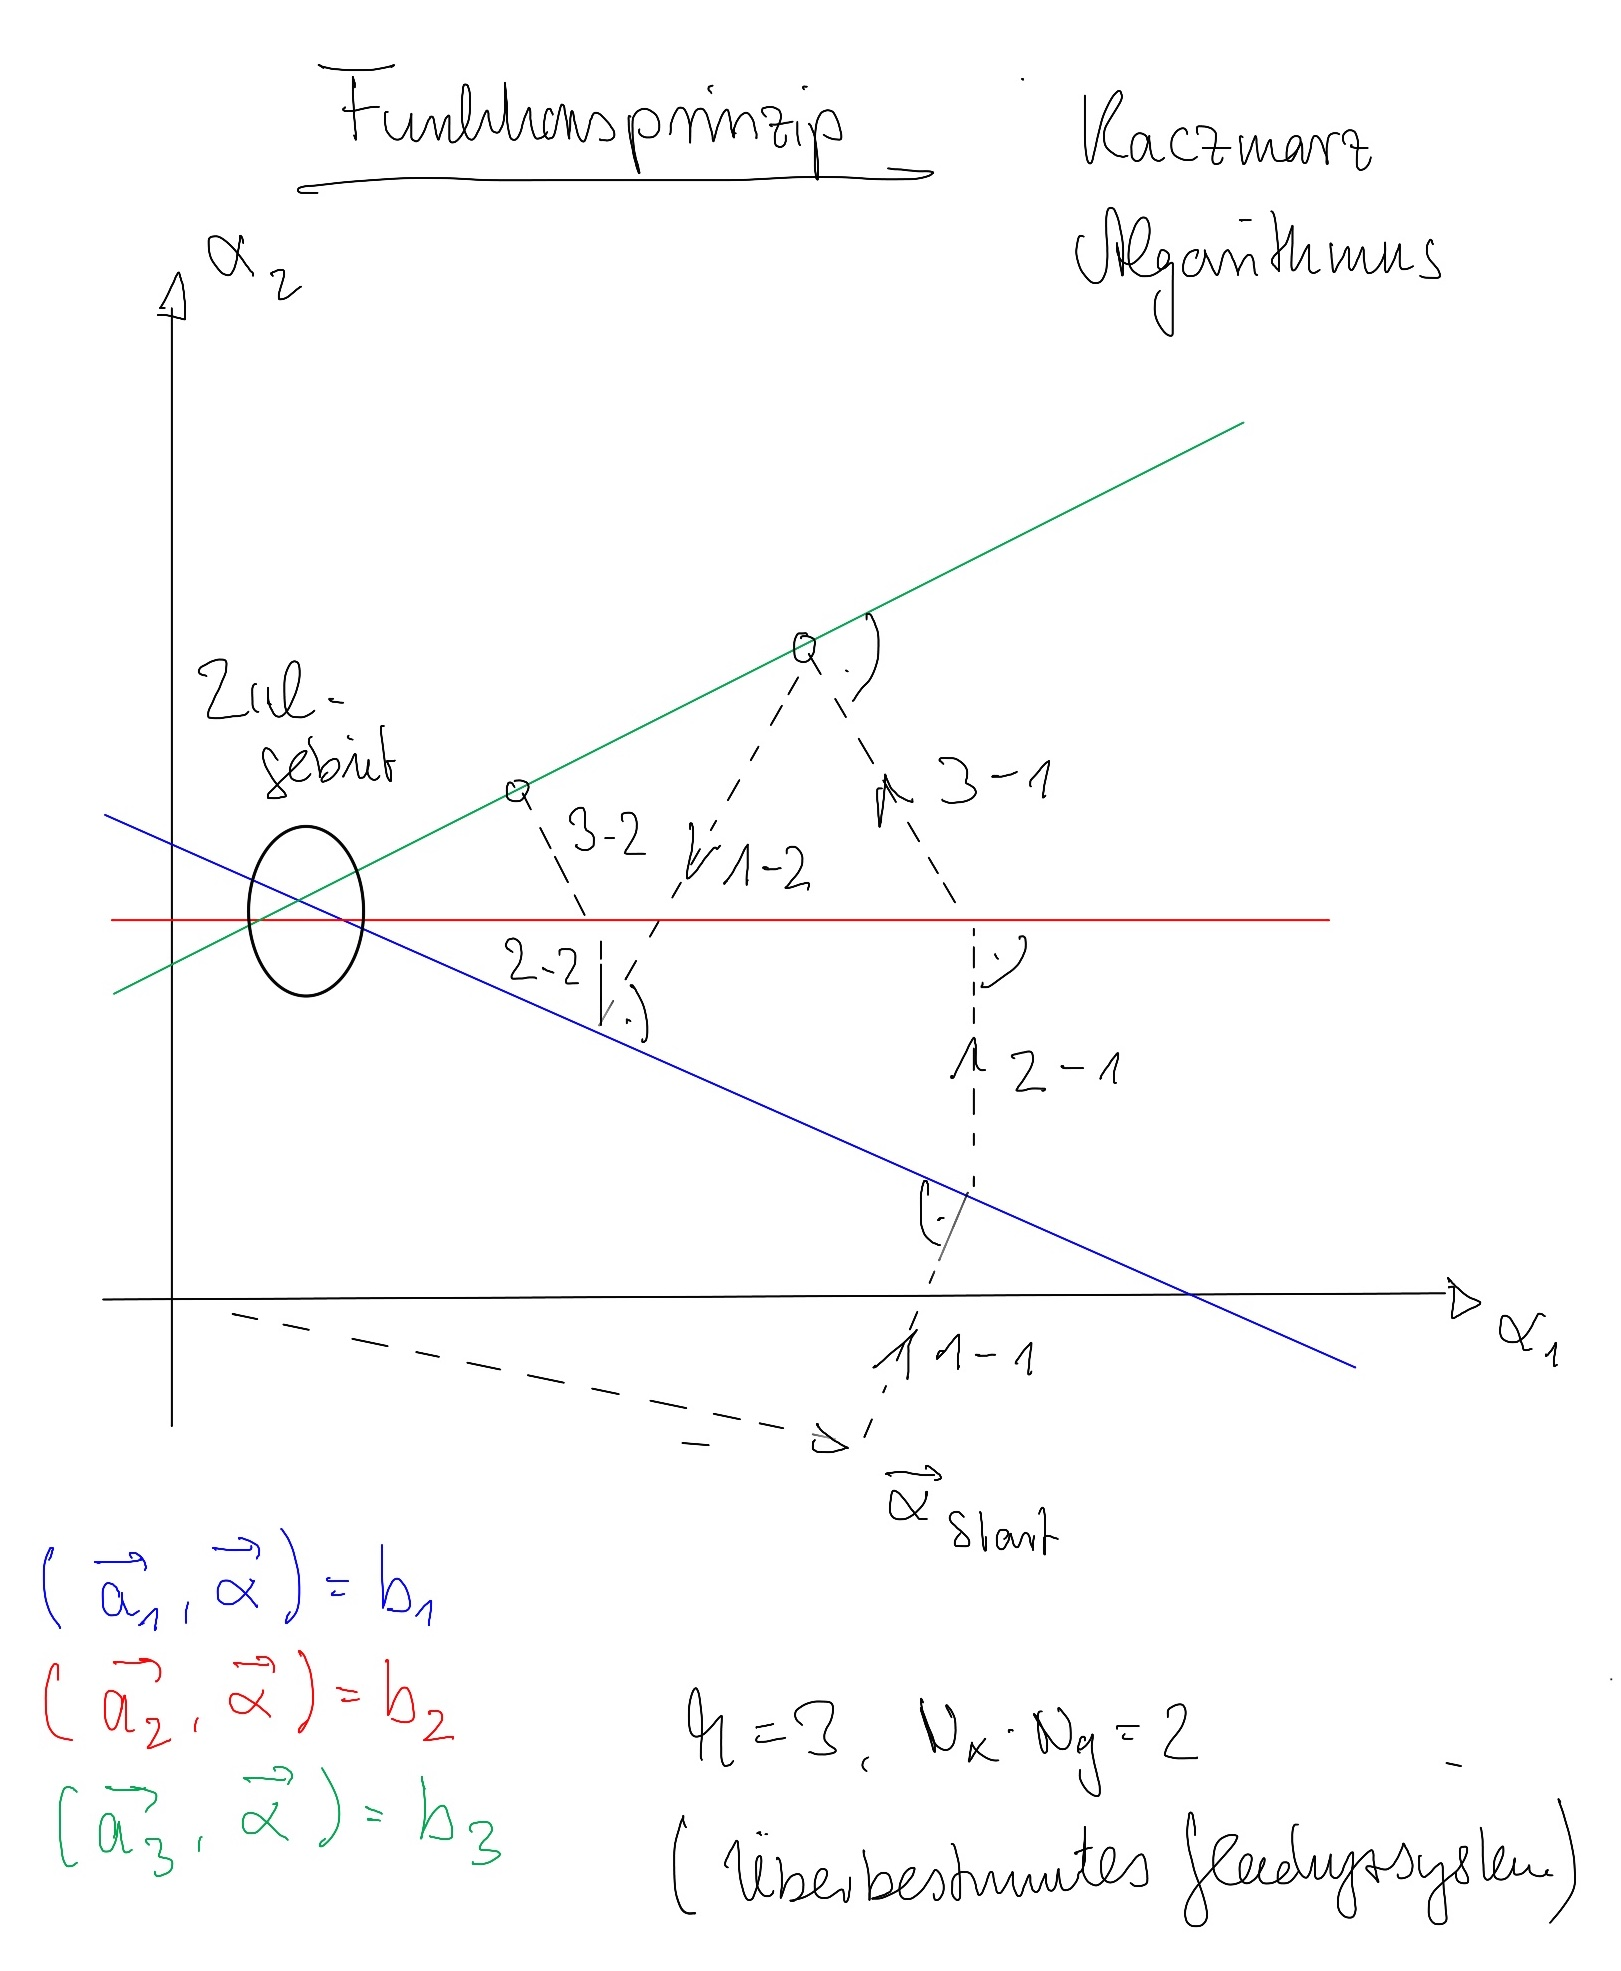

(Quelle: Fuchs, C.: Computer Tomopgrafie Vorlesungsmaterial. 2022)

### Paralleltomo Miriam, Daniel

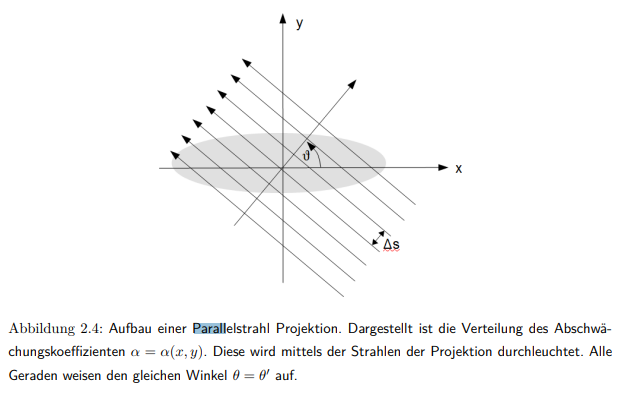

#### Parameter

- N            Zellen/Pixel pro Zeile/Spalte

- theta        Vektor mit verwendeten Winkeln

- p             Anzahl an  parallelen Strahlen pro Winkel

- d             Abstand des ersten und des letzten Strahls zueinander

- isDisp     Boolean, ob Zwischenergebnisse angezeigt werden sollen

N = 250;
theta = 0:179;
p = round(sqrt(2)*N);
d = sqrt(2)*N;
isDisp = 0;

[A, b, x, theta, d, p] = paralleltomo(N,0,theta,p,d,isDisp); %#ok<*ASGLU> 

**Relevante Rückgabewerte**

- x:  Vektor mit exakter Lösung

- A:  Koeffizientenmatrix

- b:  Vektor zur Matrix

**Lösen des Gleichungssystemes**

K = 20; % Anzahl der Iterationen
[X,info] = kaczmarz(A,b,K);  

**Anzeigen der Rekonstruktion und des Originals**

figure;
imagesc(reshape(x,N,N)), colormap gray,
axis image off
c = caxis;
title('Original');

figure
imagesc(reshape(X,N,N)), colormap gray,
axis image off
caxis(c)
title('Kaczmarz Rekonstruktion')

### Fächerstrahltomographie

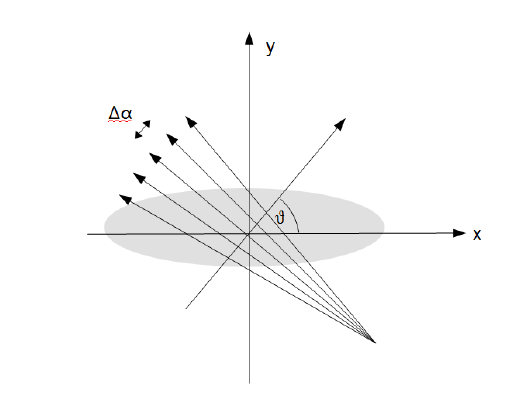

#### Parameter

- N            Zellen/Pixel pro Zeile/Spalte

- theta       Vektor mit verwendeten Winkeln

- p             Anzahl an Strahlen pro Winkel

- R            Abstand von Sender zum Mittelpunkt des Objekts

- d             Spannweite der Strahlen

- isDisp     Boolean, ob Zwischenergebnisse angezeigt werden sollen

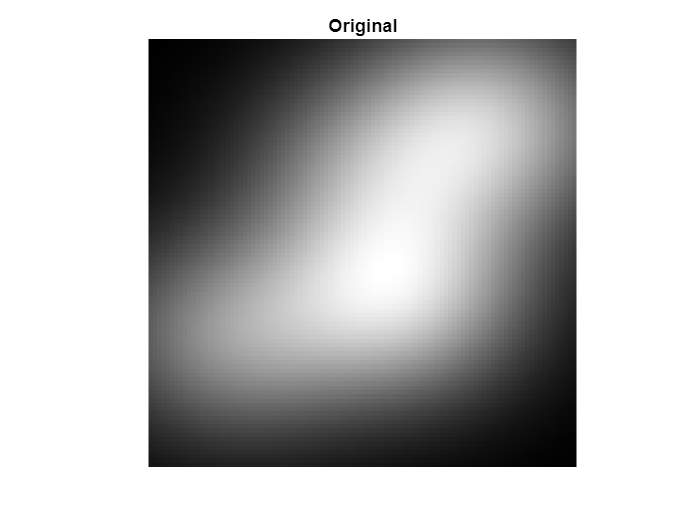

N = 100;
theta = 0:1:359;

p = round(sqrt(2)*N);
R = 2;
d = 2*atand(1/(2*R-1));
isDisp = 0;

#### Absoptionskoeffizient

Hier kann ein beliebiger Absorptionskoeffizient erstellt werden

**Beispielsweise:**

- Beispelbilder

- Einzelne Matrizen von Hand

- Phantombilder

**Phantomgallerie:**

Matlab Funktion, die verschiedene Phantombilder erzeugen kann. Diese sind besonders zum Testen von Rekonstruktionen geeignet. 

- smooth

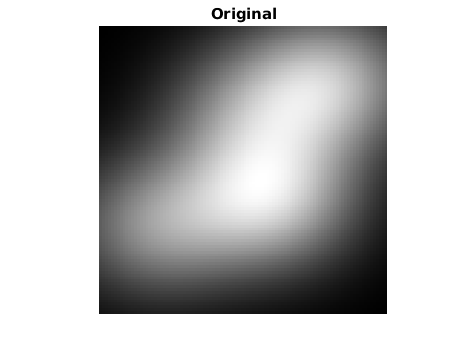

- binary

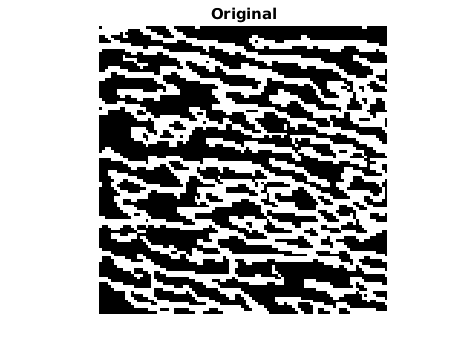

- treephases

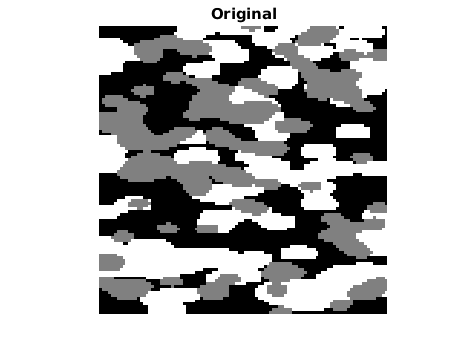

- treephasessmooth

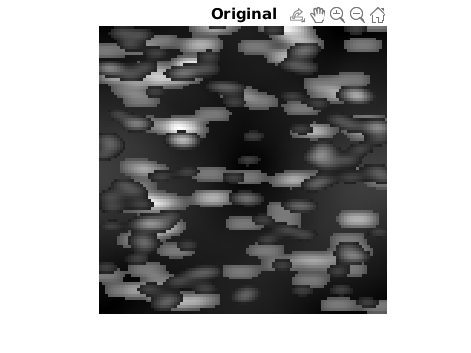

- fourphases

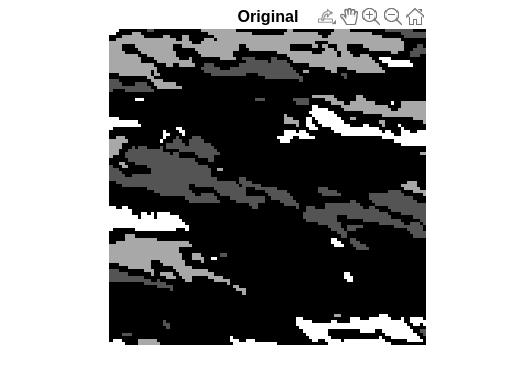

- grains

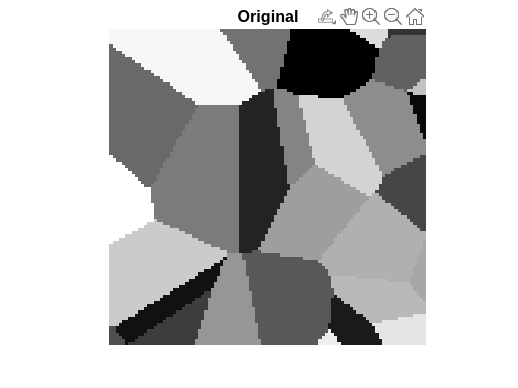

- ppower

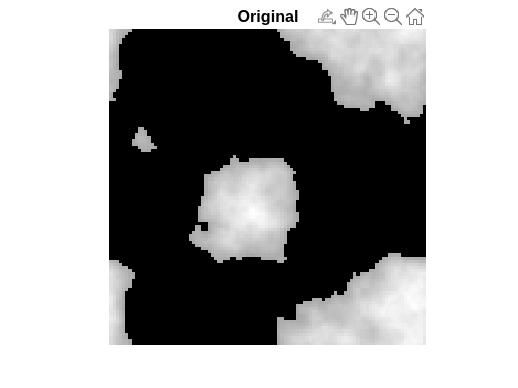

**Änderungen an *****fanbeamtomo.m:***

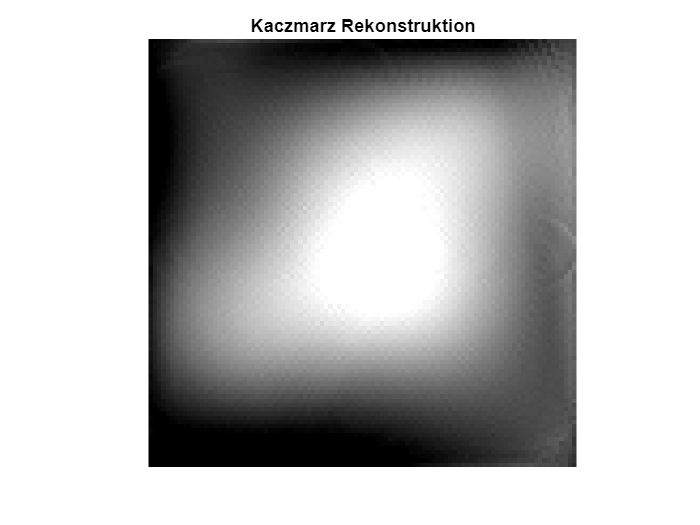

absCoeff = phantomgallery('smooth',N);


[A, b, x, theta, d, p] = fanbeamtomo(N,theta,p,R,d,isDisp, absCoeff);

**Relevante Rückgabewerte**

- x:  Vektor mit exakter Lösung

- A:  Koeffizientenmatrix

- b:  Vektor zur Matrix

#### Lösen des Gleichungssystemes

K = 5; % Anzahl der Iterationen

[X,info] = kaczmarz(A,b,K);

    0.1175



#### Anzeigen der Rekonstruktion und des Originals

figure;

    0.1426



imagesc(reshape(x,N,N)), colormap gray,
axis image off

    0.0162



c = caxis;
title('Original');

    0.1947



figure

    0.2417



imagesc(reshape(X,N,N)), colormap gray,
axis image off

    0.7231



caxis(c)
title('Kaczmarz Rekonstruktion')

#### Numerisches Vergleichen der Bilder

Berechnen der Vergleichswerte

[del1,del2,del3,del4,del5, uniformity] = bildvergleich(x,X);

del1:

disp(del1);

del2:

disp(del2);

del3:

disp(del3);

del4:

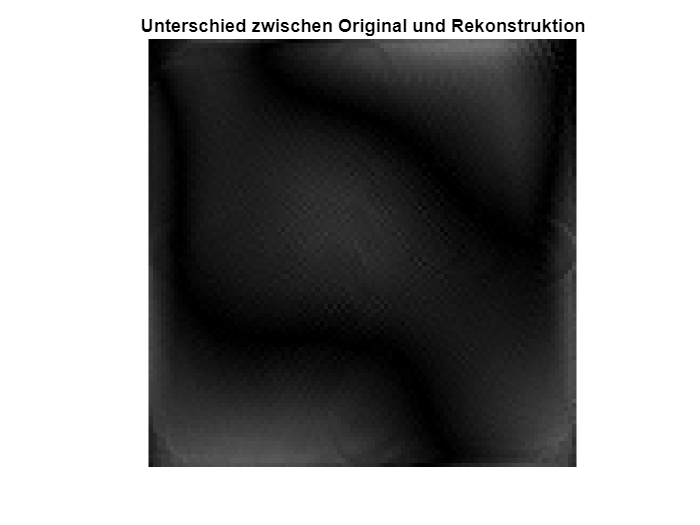

disp(del4);

del5:

disp(del5);

uniformity:

disp(uniformity);

#### Visuelles Vergleichen der Bilder 

l = abs(X-x);

figure
imagesc(reshape(l,N,N)), colormap gray,
axis image off
caxis(c)
title('Unterschied zwischen Original und Rekonstruktion')